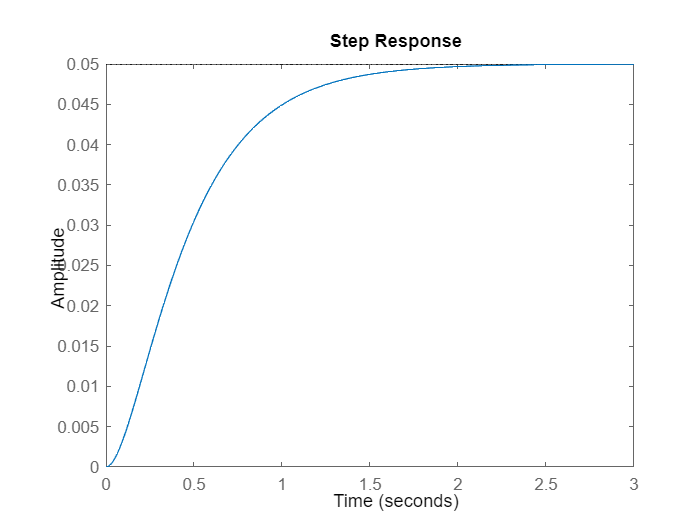

% The following is a design of a PID controller for a simple spring
% dampener system. We have
% m = 1 kg
% b = 10 N s/m
% k = 20 N/m
% F = 1 N

% Transfer function then becomes:
s = tf('s');
P = 1/(s^2 + 10*s + 20);
step(P)

We see that this output has a rise time of 1 seconds, settling time of 1.5 seconds, and a steady state error of 0.95.

Let's try and improve this.

We add a proportional gain controller.

Kp = 300;
C = pid(Kp) % The inbuilt pid function in matlab provides a time domain equation of a pid controller.

C =
 
  Kp = 300
 
P-only controller.



T = feedback(C*P, 1) % The feedback function closes the loop, the arguments are the open loop transfer function and the feedback gain.

T =
 
        300
  ----------------
  s^2 + 10 s + 320
 
Continuous-time transfer function.



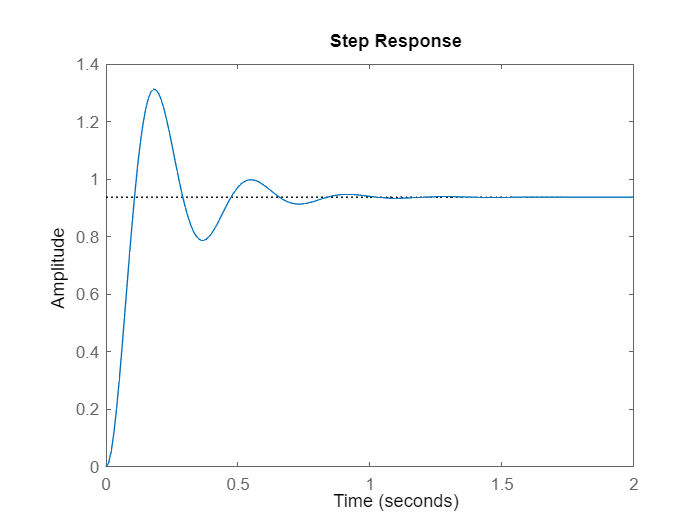


t = 0:0.01:2;
step(T, t)

The rise time and steady state error are both reduced by a significant margin, by using just a proportional controller. However the overshoot has increased.

Let's then add derivative control.

Kp = 300;
Kd = 10;
C = pid(Kp, 0, Kd)

C =
 
             
  Kp + Kd * s
             

  with Kp = 300, Kd = 10
 
Continuous-time PD controller in parallel form.



T = feedback(C*P, 1)

T =
 
     10 s + 300
  ----------------
  s^2 + 20 s + 320
 
Continuous-time transfer function.




t = 0:0.01:2;

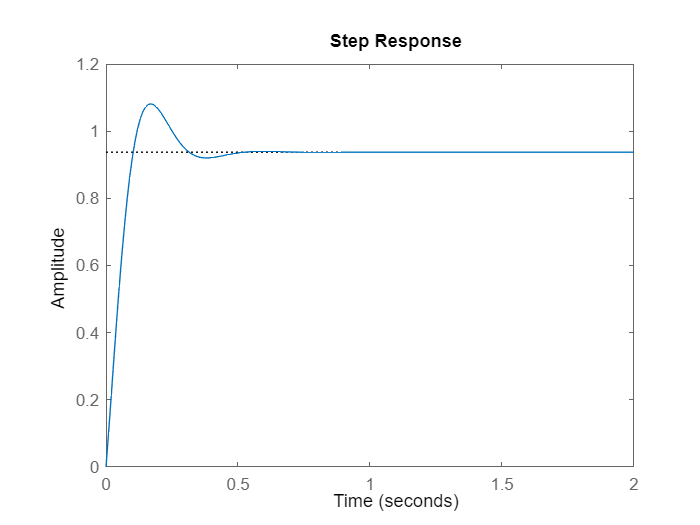

step(T, t)

The  Proportional-Derivative controller reduces the overshoot and settling time while having negligible effect on rise time and steady-state error.

We now build a PI controller.

Kp = 30;
Ki = 70;
C = pid(Kp, Ki)

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 30, Ki = 70
 
Continuous-time PI controller in parallel form.



T = feedback(C*P, 1)

T =
 
         30 s + 70
  ------------------------
  s^3 + 10 s^2 + 50 s + 70
 
Continuous-time transfer function.



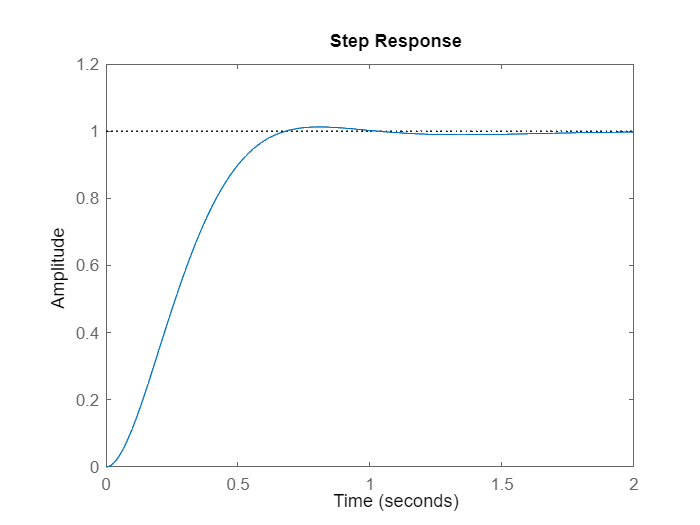


t = 0:0.01:2;
step(T, t)

The value of Kp has been reduced as it has the same effect on rise time and overshoot as Ki and the effects would add up detrimentally. The integral controller eliminates the steady-state error.

Finally, the PID controller:

Kp = 350;
Ki = 300;
Kd = 50;
C = pid(Kp, Ki, Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 350, Ki = 300, Kd = 50
 
Continuous-time PID controller in parallel form.



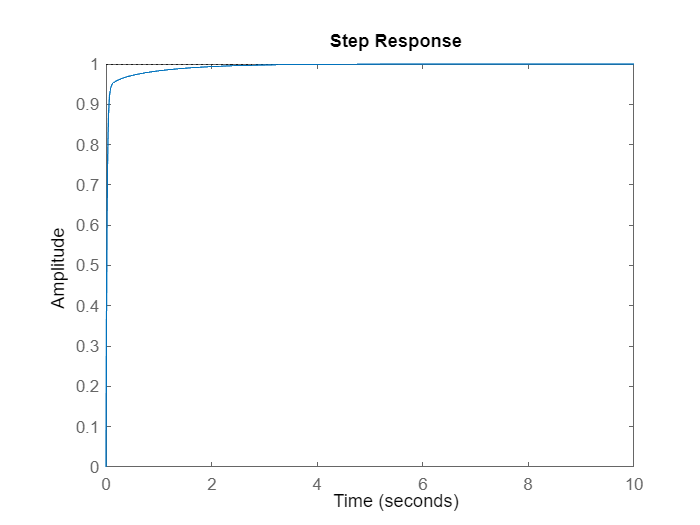

T = feedback(C*P, 1);

t = 0:0.01:10;   
step(T, t)

We find there is no overshoot, quick rise time, and no steady-state error.